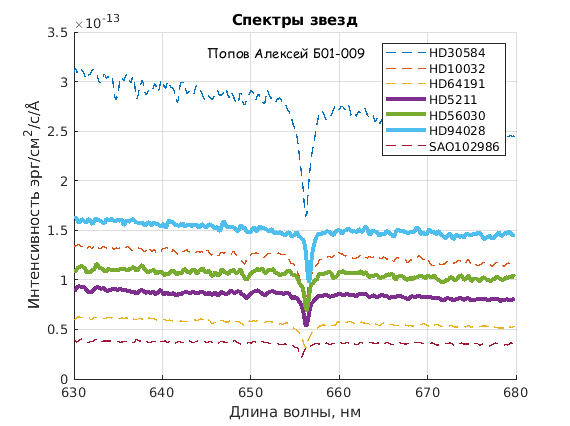

spectra     = importdata("spectra.csv");
starNames   = importdata("star_names.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");

lambdaPredicted = 656.28; %нм
speedOfLight = 299792.458; %км/с
starsCount = size(starNames, 1);

observationCount = size(spectra, 1);
lambdaEnd = lambdaStart + (observationCount - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

minIntensivities = zeros(starsCount, 2);
for i = 1:starsCount
    [minIntensivities(i,1), minIntensivities(i,2)] = min(spectra(:, i));
end

% disp(lambda)

speed = zeros(1, starsCount);

for i = 1:starsCount
    speed(i) = speedOfLight * (lambda(minIntensivities(i,2)) / lambdaPredicted - 1);
end

speed = speed';
 % disp(speed);

fg1 = figure;
hold on
for i = 1:starsCount

    if speed(i) > 0
    plot(lambda, spectra(:, i), "LineStyle","-", "LineWidth", 3);
    else
    plot(lambda, spectra(:, i), "LineStyle","- -","LineWidth", 1);
    end
    set(fg1, 'Visible', 'on');
    grid on
end

text(645, (3.3*10^(-13)), 'Попов Алексей Б01-009', 'FontName', 'Comic Sans MS');
xlabel('Длина волны, нм');
ylabel(['Интенсивность эрг/см^2/с/' char(197)]);
title({'Спектры звезд'});
legend(starNames);

movaway = starNames(speed > 0);

saveas(fg1, 'spectra.png');